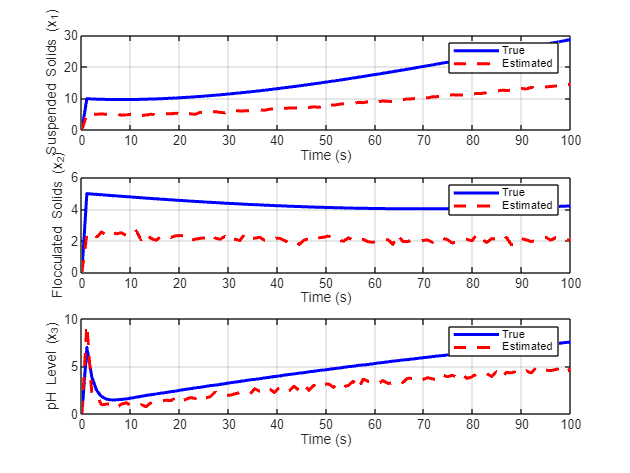

% Updated System Matrices
A = [-0.0166, 0, 0;  
     0.0016, -0.008, 0;  
     0, 0, -0.5];

B = [0.01;  
     0;  
     0.05];

C = [1, 0, 0;  
     0, 0, 1;
     0, 1, 0]; 

D = [0; 0; 0];

 



% PID Gains
Kp = 1;    % Proportional Gain
Ki = 0.1;  % Integral Gain
Kd = 0.01; % Derivative Gain

% Desired Output
pH_desired = 10;


% Kalman Filter Parameters
Q = 0.1 * eye(3); % Process noise covariance
R = 0.1 * eye(3); % Measurement noise covariance (3x3 due to 3 outputs)
P = eye(3);       % Initial estimate error covariance

% Initial Conditions
x = [10 ; 5 ; 14]; % True states
x_est = x;        % Estimated states
y = C * x;        % Output
u = 0;            % Control input
e_prev = 0;       % Previous error
int_e = 0;        % Integral of error

% Time Span for Simulation
tspan = linspace(0, 100, 100);
dt = tspan(2) - tspan(1); % Time step

% Preallocate Storage for Results
x_hist = zeros(length(tspan), length(x));
x_est_hist = zeros(length(tspan), length(x));
y_hist = zeros(length(tspan), size(C, 1));
u_hist = zeros(length(tspan), 1);

% Simulation Loop
for k = 2:length(tspan)
    % --- Kalman Filter ---
    % Predict
    x_pred = A * x_est + B * u;
    P_pred = A * P * A' + Q;

    % Measurement update (with noise)
    y_meas = C * x + sqrt(R) * randn(3, 1);

    % Update
    Kf = P_pred * C' / (C * P_pred * C' + R);
    x_est = x_pred + Kf * (y_meas - C * x_pred);
    P = (eye(3) - Kf * C) * P_pred;

    % --- PID Control ---
    % Error calculation for pH control (using x_est(3))
    e = pH_desired - x_est(3); % Use estimated pH
    de = (e - e_prev) / dt;    % Derivative of error
    int_e = int_e + e * dt;    % Integral of error

    % PID control law
    u = Kp * e + Ki * int_e + Kd * de;

    % --- System Dynamics ---
    % Update true states
    dx = A * x + B * u;
    x = x + dx * dt;

    % Update output
    y = C * x;

    % Store results
    x_hist(k, :) = x';
    x_est_hist(k, :) = x_est';
    y_hist(k, :) = y';
    u_hist(k) = u;

    % Store previous error
    e_prev = e;
end

% --- Plot Results ---
figure;
subplot(3, 1, 1);
plot(tspan, x_hist(:, 1), 'b', 'LineWidth', 2); hold on;
plot(tspan, x_est_hist(:, 1), 'r--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Suspended Solids (x_1)');
legend('True', 'Estimated');
grid on;

subplot(3, 1, 2);
plot(tspan, x_hist(:, 2), 'b', 'LineWidth', 2); hold on;
plot(tspan, x_est_hist(:, 2), 'r--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Flocculated Solids (x_2)');
legend('True', 'Estimated');
grid on;

subplot(3, 1, 3);
plot(tspan, x_hist(:, 3), 'b', 'LineWidth', 2); hold on;
plot(tspan, x_est_hist(:, 3), 'r--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('pH Level (x_3)');
legend('True', 'Estimated');
grid on;

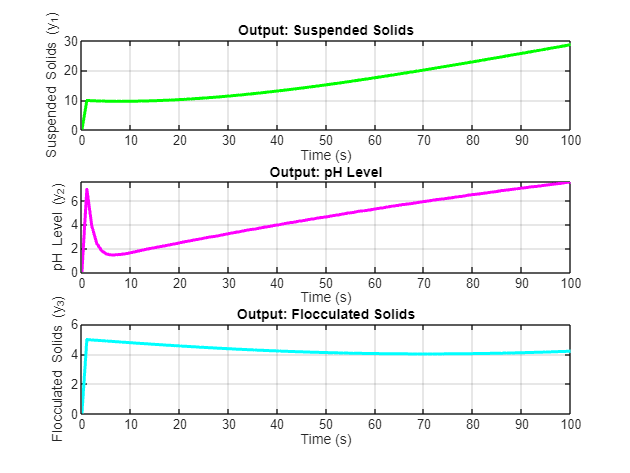


figure;
subplot(3, 1, 1);
plot(tspan, y_hist(:, 1), 'g', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Suspended Solids (y_1)');
title('Output: Suspended Solids');
grid on;

subplot(3, 1, 2); 
plot(tspan, y_hist(:, 2), 'm', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('pH Level (y_2)');
title('Output: pH Level');
grid on;

subplot(3, 1, 3);
plot(tspan, y_hist(:, 3), 'c', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Flocculated Solids (y_3)');
title('Output: Flocculated Solids');
grid on;

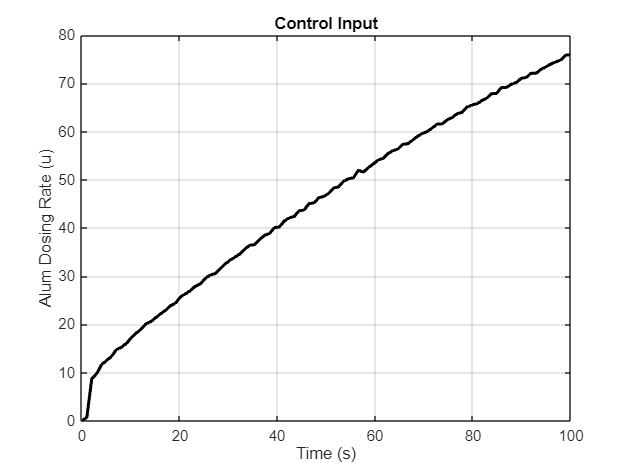


figure;
plot(tspan, u_hist, 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Alum Dosing Rate (u)');
title('Control Input');
grid on;